%--------------------------------------------------------------------------
% Physical constants
q = +1.602176565E-19; % Electron charge
m_e = 9.10938291E-31; % Electron mass
epsilon_0 = 8.854187817E-12; % \epsilon_0
h_bar = 1.054571726E-34;
w_theta = 4.7; % eV

g_fac = 1.0; % Scale factor for testing (Not really used).

%--------------------------------------------------------------------------
% Parameters for the tip


%Base radius
R_r = 250.0E-9; % [nm]
% Tip height
h_r = 500.0E-9; % [nm]
% Distance from top of tip to plane
d = 1000.0E-9; % [nm]
% Distance of plane from bottom of tip
d_plane = d + h_r;

max_xi = h_r/d + 1;
a = sqrt(d^2*R_r^2/(h_r^2+2*d*h_r) + d^2);
eta_1 = - d / a;

theta = acos(d/a);
r_tip = a*sin(theta)*tan(theta);
eta_2 = 0.0; % Defines the plane of absorption
eta = eta_1; % Defines the tip
shift_z = abs(a*eta*max_xi);

%--------------------------------------------------------------------------
% Particle
% Position in prolate spheroidal coordinates
xi_a = 1.000;
eta_a = -0.975724;
phi_a = 0.0;

% Position of the particle in x,y,z coordinates
x_a = a * sqrt(xi_a^2 - 1) * sqrt(1 - eta_a^2) * cos(phi_a);
y_a = a * sqrt(xi_a^2 - 1) * sqrt(1 - eta_a^2) * sin(phi_a);
z_a = a * xi_a * eta_a;

%-------------------------------------------------------------------------
% Caclulate x, y and z values for the tip
% Max x value, should be the same as R_r (base radius)
max_x = a*sqrt(max_xi^2-1)*sqrt(1-eta_1^2)*1;
x_tip = linspace(-max_x, max_x, 10001);
%x_tip = 2.5719e-09;
%x = 0.0;
y_tip = 0.0;

xi = sqrt(x_tip.^2/(a^2*(1-eta_1^2)*1) + 1);
z_tip = a .* xi .* eta_1;

%x_tip = 0.0;
%y_tip = 0.0;
%z_tip = a .* 1.0 .* eta_1;

%--------------------------------------------------------------------------
% Center of the sphere used for the image charge approximation
x_c = 0.0;
y_c = 0.0;
z_c = a*1.0*eta_1 - r_tip*g_fac; % Located at the top of the tip


% Distance from center of sphere (x_c, y_c, z_c) to particle (x_a, y_a, z_a).
a_b = sqrt((x_a - x_c).^2 + (y_a - y_c).^2 + (z_a - z_c).^2);
disp(a_b/1E-9)

   50.1804




% Distance of image charge from center of sphere.
b = r_tip^2/a_b;

% Vector from center of sphere to particle. Unit length.
n_a(1, :) = (x_a - x_c) ./ a_b;
n_a(2, :) = (y_a - y_c) ./ a_b;
n_a(3, :) = (z_a - z_c) ./ a_b;

% Coordinates of image charge partner.
x_b = x_c + n_a(1, :).*b;
y_b = y_c + n_a(2, :).*b;
z_b = z_c + n_a(3, :).*b;

eta_p_start = -0.971;
eta_p_end = -0.975900072948533;

xi_0 = 1.000;
xi_05 = 1.0005;
xi_2 = 1.002;
xi_4 = 1.004;
xi_6 = 1.006;

xi_end = 1.0236;


x0_s = a * sqrt(xi_0^2 - 1) * sqrt(1 - eta_p_start^2);
x0_e = a * sqrt(xi_0^2 - 1) * sqrt(1 - eta_p_end^2);
z0_s = a * xi_0 * eta_p_start;
z0_e = a * xi_0 * eta_p_end;

x05_s = a * sqrt(xi_05^2 - 1) * sqrt(1 - eta_p_start^2);
x05_e = a * sqrt(xi_05^2 - 1) * sqrt(1 - eta_p_end^2);
z05_s = a * xi_05 * eta_p_start;
z05_e = a * xi_05 * eta_p_end;

x2_s = a * sqrt(xi_2^2 - 1) * sqrt(1 - eta_p_start^2);
x2_e = a * sqrt(xi_2^2 - 1) * sqrt(1 - eta_p_end^2);
z2_s = a * xi_2 * eta_p_start;
z2_e = a * xi_2 * eta_p_end;

x4_s = a * sqrt(xi_4^2 - 1) * sqrt(1 - eta_p_start^2);
x4_e = a * sqrt(xi_4^2 - 1) * sqrt(1 - eta_p_end^2);
z4_s = a * xi_4 * eta_p_start;
z4_e = a * xi_4 * eta_p_end;

x6_s = a * sqrt(xi_6^2 - 1) * sqrt(1 - eta_p_start^2);
x6_e = a * sqrt(xi_6^2 - 1) * sqrt(1 - eta_p_end^2);
z6_s = a * xi_6 * eta_p_start;
z6_e = a * xi_6 * eta_p_end;

xend_s = a * sqrt(xi_end^2 - 1) * sqrt(1 - eta_p_start^2);
xend_e = a * sqrt(xi_end^2 - 1) * sqrt(1 - eta_p_end^2);
zend_s = a * xi_end * eta_p_start;
zend_e = a * xi_end * eta_p_end;

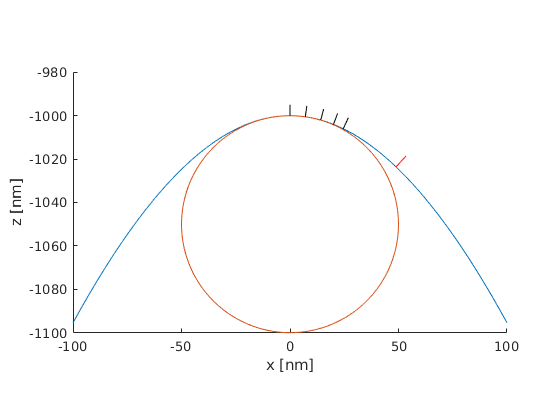

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Draw the tip, sphere and charge.
figure();
hold on
axis equal
plot(x_tip/1E-9, z_tip/1E-9); % Tip

t = linspace(0, 2*pi, 100);
x_sp = x_c + g_fac*r_tip*cos(t);
z_sp = z_c + g_fac*r_tip*sin(t);

plot(x_sp/1E-9, z_sp/1E-9); % Sphere

%plot(x_a/1E-9, z_a/1E-9, 'ok', 'MarkerFaceColor', 'k', 'MarkerSize', 2); % Charge
%plot(x_b/1E-9, z_b/1E-9, 'ok', 'MarkerFaceColor', 'r', 'MarkerSize', 2); % Partner
plot([-max_x/1E-9, max_x/1E-9], [0, 0]); % Top plane

plot([x0_s/1E-9, x0_e/1E-9], [z0_s/1E-9, z0_e/1E-9], '-k')
plot([x05_s/1E-9, x05_e/1E-9], [z05_s/1E-9, z05_e/1E-9], '-k')
plot([x2_s/1E-9, x2_e/1E-9], [z2_s/1E-9, z2_e/1E-9], '-k')
plot([x4_s/1E-9, x4_e/1E-9], [z4_s/1E-9, z4_e/1E-9], '-k')
plot([x6_s/1E-9, x6_e/1E-9], [z6_s/1E-9, z6_e/1E-9], '-k')
plot([xend_s/1E-9, xend_e/1E-9], [zend_s/1E-9, zend_e/1E-9], '-r')

xlim([-100, 100])
ylim([-1100, -980])

xlabel('x [nm]')
ylabel('z [nm]')

b_FN = 4.0/(3.0*h_bar) * sqrt(2.0*m_e*q); % eV^{-3/2} V m^{-1}
V = 500.0;

Q_0 = 1/2*log((1+cos(theta))/(1-cos(theta)));
term_1 = 3*V*log(10)/(b_FN*d*tan(theta)*Q_0) + sin(theta);
term_2 = cos(theta);

xi_0 = sqrt(term_1^2 + term_2^2)

xi_0 = 1.5815

syms xi

V = 500.0;
Q_0 = 1/2*log((1+cos(theta))/(1-cos(theta)));

a_FN = q^2/(16.0*pi^2*h_bar); % A eV V^{-2}
b_FN = 4.0/(3.0*h_bar) * sqrt(2.0*m_e*q); % eV^{-3/2} V m^{-1}
l_const = q / (4.0*pi*epsilon_0); % eV^{2} V^{-1} m

%
F(xi) = V/r_tip * tan(theta)/(Q_0*sqrt(xi^2-cos(theta)^2));

l(xi) = l_const * F(xi) / w_theta^2;

%v_y(xi) = 1 - l(xi) + 1/6*l(xi)*log(l(xi));
%t_y(xi) = 1 + l(xi)*(1/9 - 1/18*log(l(xi)));
v_y = 1.0;
t_y = 1.0;

FN(xi) = a_FN / (t_y^2 * w_theta) * F(xi)^2 * exp(-b_FN * w_theta^(3/2) * v_y / F(xi));

xi_0 = vpasolve(FN(xi)/FN(1.0)==0.001, xi, [1.0, 2.0]);
eval(xi_0)

ans = 1.0236